J_CoR = [];
% import joint cor and angle information from excel

load('HY_hand_t.mat');


[points.vertices, points.faces, points.FB, points.H] = function_loading_ply_file('HY_pos2.ply'); % target scan
points.normals = per_vertex_normals(points.vertices, points.faces);


**Data visualization**

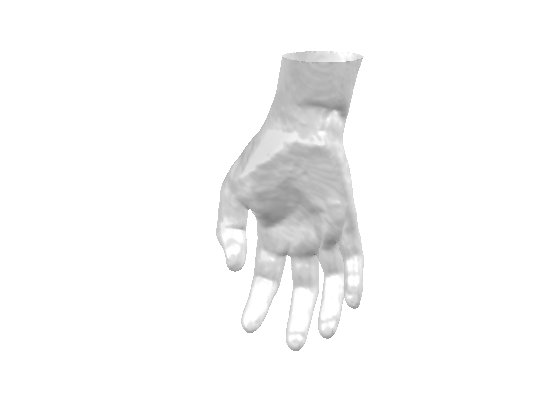

figure()
hold on
axis equal
axis off

%scatter3(mesh.vertices(:,1),mesh.vertices(:,2),mesh.vertices(:,3),'.', 'MarkerEdgeColor',[190/255, 240/255, 251/255]);
%trimesh(mesh.faces, mesh.vertices(:, 1), mesh.vertices(:, 2), mesh.vertices(:, 3), 'EdgeColor', 'none', 'FaceColor', [180/255, 180/255, 180/255], 'FaceAlpha', 0.5);
trimesh(points.faces, points.vertices(:, 1), points.vertices(:, 2), points.vertices(:, 3), 'EdgeColor', 'none', 'FaceColor', [0.8, 0.8, 0.8], 'FaceAlpha', 0.5);
%plot3(centers(:,1),centers(:,2),centers(:,3))
view([-90,0]);
camlight;
view([90, 0]);
camlight;
axis equal;
grid off;
lighting gouraud;
axis off;
view([185, 8]);
camlight;

hold off

angle = zeros(19,1);


tr_mesh = transform_angle(mesh, angle);
mesh = tr_mesh;


% mesh spheres center --> centers 
for i = 1:22
centers(i,:) = mesh.spheres{1,i}.center;
end 

centers =      0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0



% centers info --> mesh spheres center
for i = 1:22
mesh.spheres{1,i}.center = centers(i,:);
end 
